syms s;
syms kp kd ki;
syms Mgl mu J;

G = (kp*s+ki)/(J*s^3 +(mu+kd)*s^2 + (Mgl + kp)*s + ki);
taylor(1/G, s, 'ExpansionPoint', 0, 'Order', 4)

$$ans = \left(\frac{J}{\mathrm{ki}}-\frac{{\mathrm{kp}}^{3}}{{\mathrm{ki}}^{3}}+\frac{{\mathrm{kp}}^{2}\,\left(\mathrm{Mgl}+\mathrm{kp}\right)}{{\mathrm{ki}}^{3}}-\frac{\mathrm{kp}\,\left(\mathrm{kd}+\mu \right)}{{\mathrm{ki}}^{2}}\right)\,s^{3}+\left(\frac{\mathrm{kd}+\mu }{\mathrm{ki}}+\frac{{\mathrm{kp}}^{2}}{{\mathrm{ki}}^{2}}-\frac{\mathrm{kp}\,\left(\mathrm{Mgl}+\mathrm{kp}\right)}{{\mathrm{ki}}^{2}}\right)\,s^{2}+\left(\frac{\mathrm{Mgl}+\mathrm{kp}}{\mathrm{ki}}-\frac{\mathrm{kp}}{\mathrm{ki}}\right)\,s+1$$

syms z wn

f1 = Mgl/ki-2*z/wn;
f2 = (mu+kd)/ki-Mgl*kp/(ki^2)-1/(wn^2);
f3 = J/ki-kp*(mu+kd)/(ki^2)+Mgl*kp^2/(ki^3);
S = solve([f1==0, f2==0, f3==0],[kp, kd, ki]);
S.kp

$$ans = J\,{\mathrm{wn}}^{2}$$

S.kd

$$ans = \frac{4\,J\,{\mathrm{wn}}^{2}\,z^{2}-2\,\mu \,\mathrm{wn}\,z+\mathrm{Mgl}}{2\,\mathrm{wn}\,z}$$

S.ki

$$ans = \frac{\mathrm{Mgl}\,\mathrm{wn}}{2\,z}$$

g  = 9.81;                % 重力加速度[m/s^2]
l  = 0.2;                 % アームの長さ[m]
M  = 0.5;                 % アームの質量[kg]
mu = 1.5e-2;              % 粘性摩擦係数[kg*m^2/s]
J  = 1.0e-2;              % 慣性モーメント[kg*m^2]

P = tf( [0,1], [J, mu, M*g*l] );

ref = 30; % 目標角度 [deg]

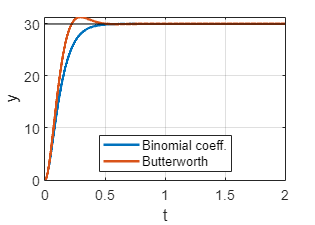

omega_n = 15;
zeta = [1, 1/sqrt(2)];
Label = ["Binomial coeff.", "Butterworth"];


t = 0:0.01:2;
figure();
for i = 1:1:2
    Msys = tf([0,omega_n^2], [1,2*zeta(i)*omega_n,omega_n^2]);
    y = step( Msys, t);
    plot(t,y*ref, 'linewidth', 2, 'DisplayName', Label(i) )
    hold on;
end
plot_set(gcf, 't', 'y', 'best')
plot(t, ref*ones(1,size(t,2)), 'k');

omega_n = 15;
zeta = 0.707;

Msys = tf([0,omega_n^2], [1,2*zeta*omega_n,omega_n^2]);

kp = omega_n^2*J

kp = 2.2500

ki = omega_n*M*g*l/(2*zeta)

ki = 10.4066

kd = 2*zeta*omega_n*J + M*g*l/(2*zeta*omega_n) - mu

kd = 0.2434

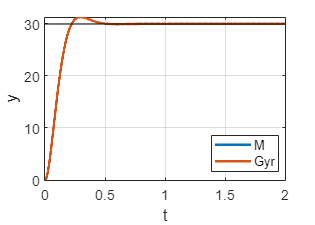

t = 0:0.01:2;
figure();

y = step( Msys, t);
plot(t,y*ref, 'linewidth', 2, 'DisplayName', 'M' )
hold on;

Gyr = tf([kp,ki], [J, mu+kd, M*g*l+kp, ki]);
y = step( Gyr, t);
plot(t,y*ref, 'linewidth', 2, 'DisplayName', 'Gyr' )
hold on;

plot_set(gcf, 't', 'y', 'best')
plot(t, ref*ones(1,size(t,2)), 'k');

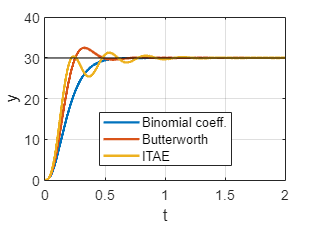

alpha1 = [3, 2, 2.15];
alpha2 = [3, 2, 1,75];
omega_n = 15;
Label = ["Binomial coeff.", "Butterworth", "ITAE"];

t = 0:0.01:2;
figure();
for i = 1:1:3
    M = tf([0, omega_n^3], [1, alpha2(i)*omega_n, alpha1(i)*omega_n^2, omega_n^3]);
    y = step( M, t);
    plot(t,y*ref, 'linewidth', 2, 'DisplayName', Label(i) )
    hold on;
end
plot_set(gcf, 't', 'y', 'best')
plot(t, ref*ones(1,size(t,2)), 'k');